# **Ricci Scalar in GW**

% Define grid
t = linspace(0, 10, 100); % Time grid
z = linspace(-10, 10, 100); % Spatial grid
[T, Z] = meshgrid(t, z);

% Define gravitational wave parameters
A_plus = 0.1; % Amplitude of h_+
A_cross = 0.1; % Amplitude of h_x
k = 1; % Wave number
omega = 1; % Frequency

% Define metric perturbations due to gravitational waves
h_plus = A_plus * cos(k * Z - omega * T);
h_cross = A_cross * sin(k * Z - omega * T);

% Compute derivatives needed for Christoffel symbols
dh_plus_dt = -omega * A_plus * sin(k * Z - omega * T);
dh_plus_dz = k * A_plus * -sin(k * Z - omega * T);
dh_cross_dt = omega * A_cross * cos(k * Z - omega * T);
dh_cross_dz = k * A_cross * cos(k * Z - omega * T);

% Compute Christoffel symbols (only relevant components)
Gamma_ztz = 0.5 * dh_plus_dt;
Gamma_ztx = 0.5 * dh_cross_dt;
Gamma_zzz = 0.5 * dh_plus_dz;
Gamma_xxz = -0.5 * dh_plus_dz;
Gamma_yyz = 0.5 * dh_plus_dz;
Gamma_xyz = 0.5 * dh_cross_dz;

% Compute Ricci tensor components
R_tt = -dh_plus_dz .* dh_plus_dz - dh_cross_dz .* dh_cross_dz;
R_xx = dh_plus_dt .* dh_plus_dz;
R_yy = -dh_plus_dt .* dh_plus_dz;
R_xy = dh_cross_dt .* dh_cross_dz;

% Compute Ricci scalar (contract Ricci tensor with inverse metric)
R_scalar = R_tt - R_xx - R_yy - 2 * R_xy;

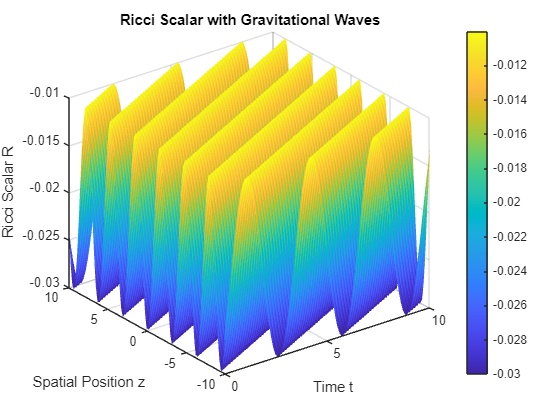

% Plot the Ricci Scalar over time and space
figure;
surf(T, Z, R_scalar, 'EdgeColor', 'none');
xlabel('Time t');
ylabel('Spatial Position z');
zlabel('Ricci Scalar R');
title('Ricci Scalar with Gravitational Waves');
colorbar;
view(3);